# TRIM & LINEARIZATION

## Initialization

clear;
global fi_flag_Simulink
newline = sprintf('\n');

## Flight Conditions

#### Assigned flight condition

fc_afc = struct();
fc_afc.altitude = 10000;
fc_afc.velocity = 350;

#### Accelerometer position analysis

fc_apa = struct()

fc_apa = struct with no fields.


fc_apa.altitude = 15000;
fc_apa.velocity = 500;

## Run Trim

#### Initial guess + setup

FC_flag = 1; % Trim for steady wings-level flight
thrust = 5000;          % thrust, lbs
elevator = -0.09;       % elevator, degrees
alpha = 8.49;              % AOA, degrees
rudder = -0.01;             % rudder angle, degrees
aileron = 0.01;            % aileron, degrees

#### HiFi AFC

disp('Trimming High Fidelity Model AFC:');

Trimming High Fidelity Model AFC:


fi_flag_Simulink = 1;
[trim_state_hi, trim_thrust_hi, trim_control_hi, dLEF, xu_hi] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,2);

Trim Values and Cost:
cost   = 7.9921e-06
thrust = 2536.0707 lb
elev   = -3.7245 deg
ail    = 0.10993 deg
rud    = -0.013233 deg
alpha  = 8.6374 deg
dLEF   = 12.6998 deg
Vel.   = 350ft/s


trim_state_lin = trim_state_hi; trim_thrust_lin = trim_thrust_hi; trim_control_lin = trim_control_hi;
operating_point = operpoint('LIN_F16Block');

operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_hi = linearize('LIN_F16Block');

disp(' ');

#### LoFi AFC

disp('Trimming Low Fidelity Model AFC:');

Trimming Low Fidelity Model AFC:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_afc.velocity, fc_afc.altitude, FC_flag,3);

Trim Values and Cost:
cost   = 9.0255e-30
thrust = 2549.7407 lb
elev   = -3.8466 deg
ail    = -3.5741e-16 deg
rud    = -1.8619e-14 deg
alpha  = 8.8116 deg
dLEF   = 0 deg
Vel.   = 350ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators

operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo = linearize('LIN_F16Block');

disp(' ');

#### HiFi APA

disp('Trimming High Fidelity Model APA:');

Trimming High Fidelity Model APA:


fi_flag_Simulink = 1;
[trim_state_hi, trim_thrust_hi, trim_control_hi, dLEF, xu_hi] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_apa.velocity, fc_apa.altitude, FC_flag,2);

Trim Values and Cost:
cost   = 7.1856e-06
thrust = 2109.4129 lb
elev   = -2.2441 deg
ail    = -0.093578 deg
rud    = 0.094469 deg
alpha  = 4.5307 deg
dLEF   = 6.2816 deg
Vel.   = 500ft/s


trim_state_lin = trim_state_hi; trim_thrust_lin = trim_thrust_hi; trim_control_lin = trim_control_hi;
operating_point = operpoint('LIN_F16Block');

operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_hi = linearize('LIN_F16Block');

disp(' ');

#### LoFi APA

disp('Trimming Low Fidelity Model APA:');

Trimming Low Fidelity Model APA:


fi_flag_Simulink = 0;
[trim_state_lo, trim_thrust_lo, trim_control_lo, dLEF, xu_lo] = trim_F16_Modified(thrust, elevator, alpha, aileron, rudder, fc_apa.velocity, fc_apa.altitude, FC_flag,18);

Trim Values and Cost:
cost   = 4.2881e-29
thrust = 2120.6214 lb
elev   = -2.4607 deg
ail    = 4.2733e-15 deg
rud    = 3.6479e-14 deg
alpha  = 4.4655 deg
dLEF   = 0 deg
Vel.   = 500ft/s


trim_state_lin = trim_state_lo; trim_thrust_lin = trim_thrust_lo; trim_control_lin = trim_control_lo;
operating_point = operpoint('LIN_F16Block'); % retrieves initial conditions from integrators

operating_point.Inputs(1).u = trim_thrust_lin; operating_point.Inputs(2).u = trim_control_lin(1);
operating_point.Inputs(3).u = trim_control_lin(2); operating_point.Inputs(4).u = trim_control_lin(3);
SS_lo = linearize('LIN_F16Block');

disp(' ');

## Block Diagram

disp("CHECK BLOCK DIAGRAM (LIN_F16Block) TO ENSURE CORRECT STATE-SPACE!");

CHECK BLOCK DIAGRAM (LIN_F16Block) TO ENSURE CORRECT STATE-SPACE!


disp(' ');

## Linearization

#### Linearized output equation for normal acc. @ CoG

disp("C MATRIX =");

C MATRIX =


disp(SS_lo.C(19,:));

         0         0   -0.0000         0   -0.0000         0    0.0040    9.9298         0         0    0.9664         0         0    0.0208         0         0



disp(' ');

disp("D MATRIX =");

D MATRIX =


disp(SS_lo.D(19,:));

     0     0     0     0



disp(' ');

#### Transfer function

[tf_num,tf_den] = ss2tf(SS_lo.A,SS_lo.B,SS_lo.C,SS_lo.D,2);
tf_num = tf_num(19,:);
disp("TRANSFER FUNCTION =")

TRANSFER FUNCTION =


tf_an_de = tf(tf_num,tf_den);

% I made this chage to get rid of cancel pole-zero pairs and simplify the
% tf
tf_an_de_minreal = minreal(tf_an_de)

tf_an_de_minreal =
 
         0.421 s^7 + 15.17 s^6 + 75.29 s^5 - 1646 s^4 - 9035 s^3 + 31.47 s^2 + 0.5024 s - 1.248e-10
  --------------------------------------------------------------------------------------------------------
  s^8 + 62.13 s^7 + 1319 s^6 + 1.024e04 s^5 + 1.514e04 s^4 + 1.695e04 s^3 + 238.1 s^2 + 119.6 s - 9.14e-12
 
Continuous-time transfer function.


**Step Response**

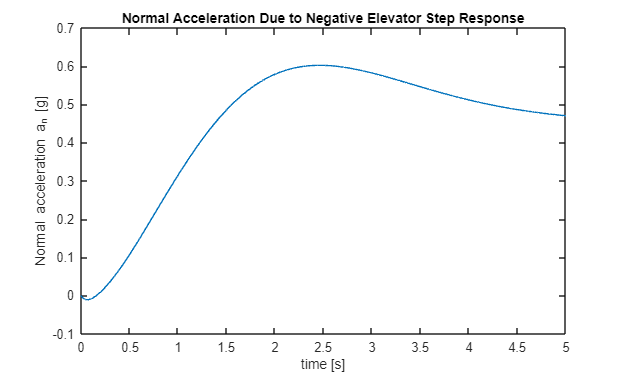

time_vector = 0:0.001:5;

[y,t] = step(-tf_an_de_minreal, time_vector);

plot(t, y)
xlabel("time [s]")
ylabel("Normal acceleration a_n [g]")
title("Normal Acceleration Due to Negative Elevator Step Response")
set(gcf,'units','points','position',[0,0, 500, 300])


figure;

**Zeros and Poles**

zero(tf_an_de_minreal)

ans =   -20.2000
  -20.2000
    9.7597
   -5.3925
    0.0094
   -0.0059
    0.0000


pole(tf_an_de_minreal)

ans =  -20.1999 + 0.0000i
 -20.2001 + 0.0001i
 -20.2001 - 0.0001i
  -0.7621 + 1.2051i
  -0.7621 - 1.2051i
  -0.0039 + 0.0844i
  -0.0039 - 0.0844i
   0.0000 + 0.0000i


## Varying Accelerometer Position

%{
clf
hold on

time_vector = 0:0.001:5

style_list = ['-', '--', '.-', ':', '-', '--'];
width_list = [1, 1, 1, 1, 2, 2];

x_a_lst = [0, 5, 5.9, 6, 7, 15];

tf_lst = [];
zero_lst = [];
s = tf('s');
for i = 1:length(x_a_lst)
    x_a = x_a_lst(i) * 0.3048;
  
    tf_xa = tf_an_de_minreal;

    tf_lst = [tf_lst, tf_xa];
    zero_lst = [zero_lst, zero(tf_xa)];

    [y,t] = step(tf_xa, time_vector);
    
    plot(t,y, 'LineWidth', width_list(i), ...
         'DisplayName', sprintf("%3.1f", x_a_lst(i)))

end
xlabel('time [s]')
ylabel('a_n [g units]')
title('Normal acceleration due to elevtor step response')
legend()
set(gcf, 'units', 'points', 'position', [0,0,500,300])

hold off
figure;

zero_lst
%}